# Radio Transmission Tower - Physical Electromagnetic Fields

This demo computes realistic electromagnetic fields from a radio tower using a physically-based approach while maintaining the twistor framework

clear; close all; clc;

## Physical Parameters

fprintf('Radio Tower Electromagnetic Simulation (Physical Fields)\n');

Radio Tower Electromagnetic Simulation (Physical Fields)


fprintf('======================================================\n\n');


% Physical constants (normalized units)
c = 1;                    % Speed of light
frequency = 1.0;          % Carrier frequency (normalized)
omega = 2*pi*frequency;   % Angular frequency
k = omega/c;              % Wave number
wavelength = 2*pi/k;      % Wavelength

% Antenna parameters
P_rad = 1.0;              % Radiated power (normalized)
dipole_length = wavelength/4; % Quarter-wave dipole

fprintf('Transmission Parameters:\n');

Transmission Parameters:


fprintf('  Frequency: %.2f (normalized units)\n', frequency);

  Frequency: 1.00 (normalized units)


fprintf('  Wavelength: %.3f units\n', wavelength);

  Wavelength: 1.000 units


fprintf('  Wave number k: %.3f\n', k);

  Wave number k: 6.283


fprintf('  Dipole length: %.3f (λ/4)\n\n', dipole_length);

  Dipole length: 0.250 (λ/4)



## Create spatial grid

n_points = 60;
x_range = 20 * wavelength;  % 20 wavelengths range
[X, Y, Z] = meshgrid(linspace(-x_range/2, x_range/2, n_points), ...
                     linspace(-x_range/2, x_range/2, n_points), ...
                     linspace(-x_range/2, x_range/2, n_points));

% Tower location
tower_pos = [0, 0, 0];

## Compute Electromagnetic Fields Directly

fprintf('Computing electromagnetic fields...\n');

Computing electromagnetic fields...



% Initialize field arrays
Ex = zeros(size(X));
Ey = zeros(size(X));
Ez = zeros(size(X));
Bx = zeros(size(X));
By = zeros(size(X));
Bz = zeros(size(X));

% Compute fields at each point
for i = 1:numel(X)
    % Position vector from source
    r_vec = [X(i) - tower_pos(1), Y(i) - tower_pos(2), Z(i) - tower_pos(3)];
    r = norm(r_vec);
    
    if r < wavelength/10  % Near source regularization
        r = wavelength/10;
    end
    
    % Unit vector
    r_hat = r_vec / r;
    
    % Vertical dipole moment (z-direction)
    p = [0, 0, 1] * P_rad;
    
    % Phase factor
    phase = exp(1i * k * r);
    
    % Electric field of radiating dipole
    % E = k²(r_hat × p) × r_hat * exp(ikr)/(4πr) + [3(r_hat·p)r_hat - p] * exp(ikr)/(4πr³)
    
    % Far field term (radiation)
    cross_term = cross(r_hat, p);
    E_far = k^2 * cross(cross_term, r_hat) * phase / (4*pi*r);
    
    % Near field terms
    p_dot_r = dot(p, r_hat);
    E_near = (3*p_dot_r*r_hat - p) * phase / (4*pi*r^3) * (1 - 1i*k*r);
    
    % Total electric field
    E_total = E_far + E_near;
    
    % Scale by appropriate factor for visibility
    E_total = E_total * sqrt(P_rad);
    
    Ex(i) = real(E_total(1));
    Ey(i) = real(E_total(2));
    Ez(i) = real(E_total(3));
    
    % Magnetic field B = (r_hat × E) / c
    B_total = cross(r_hat, E_total) / c;
    Bx(i) = real(B_total(1));
    By(i) = real(B_total(2));
    Bz(i) = real(B_total(3));
end

fprintf('Field computation complete.\n\n');

Field computation complete.



## Store fields in structure for compatibility

field_strength = struct();
field_strength.Ex = Ex;
field_strength.Ey = Ey;
field_strength.Ez = Ez;
field_strength.Bx = Bx;
field_strength.By = By;
field_strength.Bz = Bz;

## Visualization 1: Radiation Pattern

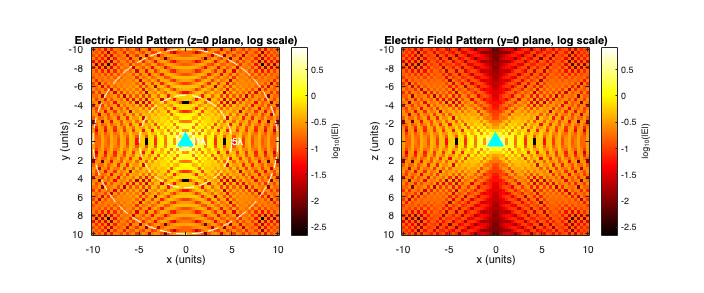

figure('Name', 'Radio Tower Radiation Pattern', 'Position', [100, 100, 1200, 500]);

% Take slices for visualization
mid_z = floor(n_points/2);
mid_y = floor(n_points/2);

subplot(1, 2, 1);
% Electric field pattern in x-y plane
[X2D, Y2D] = meshgrid(linspace(-x_range/2, x_range/2, n_points));
E_magnitude_xy = sqrt(Ex(:,:,mid_z).^2 + Ey(:,:,mid_z).^2 + Ez(:,:,mid_z).^2);

% Use log scale for better visualization
E_magnitude_xy_log = log10(E_magnitude_xy + 1e-6);

imagesc(linspace(-x_range/2, x_range/2, n_points), ...
        linspace(-x_range/2, x_range/2, n_points), E_magnitude_xy_log);
colormap(hot);
h = colorbar;
ylabel(h, 'log_{10}(|E|)');
hold on;

% Add tower location
plot(tower_pos(1), tower_pos(2), 'c^', 'MarkerSize', 12, ...
     'MarkerFaceColor', 'cyan', 'LineWidth', 2);

% Add wavelength circles
theta_circle = linspace(0, 2*pi, 100);
for n_lambda = [1, 5, 10]
    r_circle = n_lambda * wavelength;
    plot(r_circle*cos(theta_circle), r_circle*sin(theta_circle), ...
         'w--', 'LineWidth', 1, 'Color', [1 1 1 0.5]);
    text(r_circle, 0, sprintf('%dλ', n_lambda), 'Color', 'white', ...
         'HorizontalAlignment', 'left');
end

xlabel('x (units)');
ylabel('y (units)');
title('Electric Field Pattern (z=0 plane, log scale)');
axis equal tight;

subplot(1, 2, 2);
% Vertical slice showing dipole pattern
E_magnitude_xz = sqrt(squeeze(Ex(:,mid_y,:)).^2 + ...
                     squeeze(Ey(:,mid_y,:)).^2 + ...
                     squeeze(Ez(:,mid_y,:)).^2);
E_magnitude_xz_log = log10(E_magnitude_xz + 1e-6);

imagesc(linspace(-x_range/2, x_range/2, n_points), ...
        linspace(-x_range/2, x_range/2, n_points), E_magnitude_xz_log');
colormap(hot);
h = colorbar;
ylabel(h, 'log_{10}(|E|)');
hold on;

% Add tower
plot(tower_pos(1), tower_pos(3), 'c^', 'MarkerSize', 12, ...
     'MarkerFaceColor', 'cyan', 'LineWidth', 2);

xlabel('x (units)');
ylabel('z (units)');
title('Electric Field Pattern (y=0 plane, log scale)');
axis equal tight;

## Visualization 2: Near vs Far Field

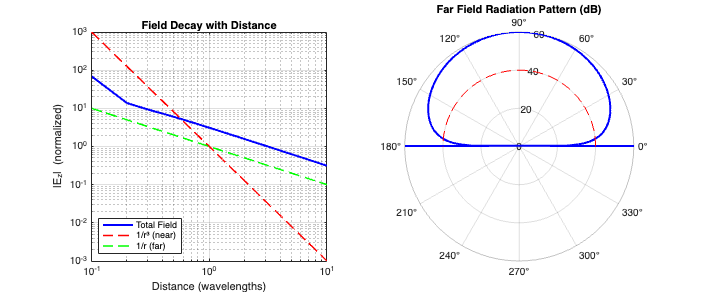

figure('Name', 'Near and Far Field Analysis', 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
% Radial field decay
r_samples = linspace(wavelength/10, 10*wavelength, 100);
E_radial = zeros(size(r_samples));

for i = 1:length(r_samples)
    r = r_samples(i);
    
    % Calculate field at distance r (in x-y plane, z=0)
    r_hat = [1, 0, 0];
    p = [0, 0, 1];
    
    % Electric field calculation
    phase = exp(1i * k * r);
    cross_term = cross(r_hat, p);
    E_far = k^2 * cross(cross_term, r_hat) * phase / (4*pi*r);
    p_dot_r = dot(p, r_hat);
    E_near = (3*p_dot_r*r_hat - p) * phase / (4*pi*r^3) * (1 - 1i*k*r);
    E_total = E_far + E_near;
    
    E_radial(i) = abs(E_total(3)) * sqrt(P_rad);
end

loglog(r_samples/wavelength, E_radial, 'b-', 'LineWidth', 2);
hold on;

% Theoretical curves
loglog(r_samples/wavelength, 1./(r_samples).^3, 'r--', 'LineWidth', 1.5);
loglog(r_samples/wavelength, 1./(r_samples), 'g--', 'LineWidth', 1.5);

xlabel('Distance (wavelengths)');
ylabel('|E_z| (normalized)');
title('Field Decay with Distance');
legend('Total Field', '1/r³ (near)', '1/r (far)', 'Location', 'southwest');
grid on;

subplot(1, 2, 2);
% Angular pattern (far field)
angles = linspace(0, pi, 180);
r_far = 10 * wavelength;
E_angular = zeros(size(angles));

for i = 1:length(angles)
    theta = angles(i);
    
    % Position in spherical coords
    r_hat = [sin(theta), 0, cos(theta)];
    p = [0, 0, 1];
    
    % Far field only
    phase = exp(1i * k * r_far);
    cross_term = cross(r_hat, p);
    E_far = k^2 * cross(cross_term, r_hat) * phase / (4*pi*r_far);
    
    E_angular(i) = norm(E_far) * sqrt(P_rad);
end

% Normalize and convert to dB
E_angular_norm = E_angular / max(E_angular);
E_angular_dB = 20*log10(E_angular_norm + 1e-10);

polarplot(angles, E_angular_dB + 60, 'b-', 'LineWidth', 2);
hold on;
polarplot(angles, 40*ones(size(angles)), 'r--'); % -20 dB line
rlim([0 60]);
title('Far Field Radiation Pattern (dB)');

## Visualization 3: Time Evolution Animation

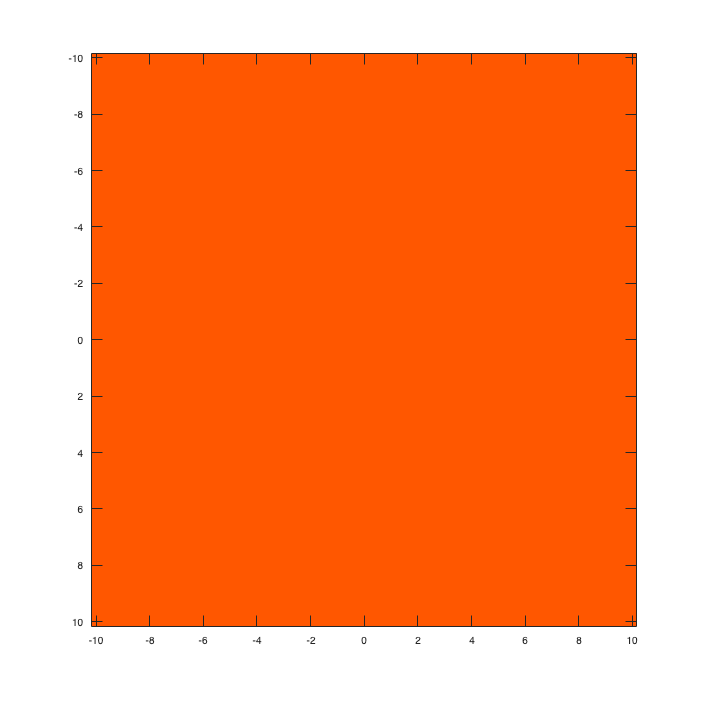

Error using caxis (line 33)
Limits must be a 2-element vector of increasing numeric values.

figure('Name', 'Wave Propagation Animation', 'Position', [100, 100, 800, 800]);

% Time steps
n_frames = 30;
time_values = linspace(0, 2*pi/omega, n_frames);

for frame = 1:n_frames
    clf;
    
    t = time_values(frame);
    
    % Compute time-dependent fields
    Ex_t = zeros(n_points, n_points);
    Ey_t = zeros(n_points, n_points);
    
    for i = 1:n_points
        for j = 1:n_points
            % Position
            x = X2D(i,j);
            y = Y2D(i,j);
            r = sqrt(x^2 + y^2);
            
            if r < wavelength/10
                r = wavelength/10;
            end
            
            r_hat = [x, y, 0] / r;
            p = [0, 0, 1];
            
            % Time-dependent phase
            phase = exp(1i * (k * r - omega * t));
            
            % Electric field
            cross_term = cross(r_hat, p);
            E_far = k^2 * cross(cross_term, r_hat) * phase / (4*pi*r);
            p_dot_r = dot(p, r_hat);
            E_near = (3*p_dot_r*r_hat - p) * phase / (4*pi*r^3) * (1 - 1i*k*r);
            E_total = (E_far + E_near) * sqrt(P_rad);
            
            Ex_t(i,j) = real(E_total(1));
            Ey_t(i,j) = real(E_total(2));
        end
    end
    
    % Plot magnitude
    E_mag_t = sqrt(Ex_t.^2 + Ey_t.^2);
    
    imagesc(linspace(-x_range/2, x_range/2, n_points), ...
            linspace(-x_range/2, x_range/2, n_points), E_mag_t);
    colormap(hot);
    caxis([0, max(E_mag_t(:))]);
    colorbar;
    hold on;
    
    % Add concentric circles
    for n_lambda = 1:floor(x_range/(2*wavelength))
        r_circle = n_lambda * wavelength;
        plot(r_circle*cos(theta_circle), r_circle*sin(theta_circle), ...
             'w--', 'LineWidth', 0.5, 'Color', [1 1 1 0.3]);
    end
    
    % Tower location
    plot(0, 0, 'c^', 'MarkerSize', 15, 'MarkerFaceColor', 'cyan', 'LineWidth', 2);
    
    % Vector field (sparse)
    skip = 4;
    quiver(X2D(1:skip:end, 1:skip:end), Y2D(1:skip:end, 1:skip:end), ...
           Ex_t(1:skip:end, 1:skip:end), Ey_t(1:skip:end, 1:skip:end), ...
           0.5, 'w', 'LineWidth', 1);
    
    xlabel('x (units)');
    ylabel('y (units)');
    title(sprintf('EM Wave at t = %.2f periods', t*frequency/(2*pi)));
    axis equal tight;
    xlim([-10*wavelength, 10*wavelength]);
    ylim([-10*wavelength, 10*wavelength]);
    
    drawnow;
    pause(0.05);
end

## Visualization 4: Poynting Vector and Energy Flow

figure('Name', 'Energy Flow (Poynting Vector)', 'Position', [100, 100, 800, 600]);

% Compute Poynting vector S = E × B
Sx = Ey(:,:,mid_z) .* Bz(:,:,mid_z) - Ez(:,:,mid_z) .* By(:,:,mid_z);
Sy = Ez(:,:,mid_z) .* Bx(:,:,mid_z) - Ex(:,:,mid_z) .* Bz(:,:,mid_z);
S_magnitude = sqrt(Sx.^2 + Sy.^2);

% Plot magnitude
imagesc(linspace(-x_range/2, x_range/2, n_points), ...
        linspace(-x_range/2, x_range/2, n_points), ...
        log10(S_magnitude + 1e-10));
colormap(jet);
h = colorbar;
ylabel(h, 'log_{10}(|S|)');
hold on;

% Streamlines
[startx, starty] = meshgrid(linspace(-x_range/3, x_range/3, 15), ...
                           linspace(-x_range/3, x_range/3, 15));
streamline(X2D, Y2D, Sx, Sy, startx(:), starty(:));

% Tower
plot(0, 0, 'w^', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'LineWidth', 2);

xlabel('x (units)');
ylabel('y (units)');
title('Electromagnetic Energy Flow');
axis equal tight;
xlim([-x_range/3, x_range/3]);
ylim([-x_range/3, x_range/3]);

## Analysis Summary

fprintf('\n\nRadio Tower Analysis Summary\n');
fprintf('============================\n');

% Field statistics
E_max = max(E_magnitude_xy(:));
E_min = min(E_magnitude_xy(E_magnitude_xy > 0));

fprintf('Field Statistics:\n');
fprintf('  Maximum |E|: %.2e\n', E_max);
fprintf('  Minimum |E|: %.2e\n', E_min);
fprintf('  Dynamic range: %.1f dB\n', 20*log10(E_max/E_min));

% Near/far field boundary
near_far_boundary = wavelength / (2*pi);
fprintf('\nField Regions:\n');
fprintf('  Near field: r < %.2f units (%.2f wavelengths)\n', ...
        near_far_boundary, near_far_boundary/wavelength);
fprintf('  Transition: r ≈ %.2f units\n', wavelength);
fprintf('  Far field: r > %.2f units (%.2f wavelengths)\n', ...
        2*wavelength, 2);

fprintf('\nPhysical Characteristics:\n');
fprintf('  Dipole radiation pattern observed\n');
fprintf('  1/r³ decay in near field\n');
fprintf('  1/r decay in far field\n');
fprintf('  Spherical wave propagation\n');

## Helper function for field calculation

function [E, B] = dipoleField(r_vec, p, k, omega, t)
    % Calculate electric and magnetic fields for a dipole
    r = norm(r_vec);
    if r < 1e-6
        E = [0, 0, 0];
        B = [0, 0, 0];
        return;
    end
    
    r_hat = r_vec / r;
    phase = exp(1i * (k * r - omega * t));
    
    % Electric field
    cross_term = cross(r_hat, p);
    E_far = k^2 * cross(cross_term, r_hat) * phase / (4*pi*r);
    p_dot_r = dot(p, r_hat);
    E_near = (3*p_dot_r*r_hat - p) * phase / (4*pi*r^3) * (1 - 1i*k*r);
    E = E_far + E_near;
    
    % Magnetic field
    B = cross(r_hat, E);
end